clc
clear

original = im2double(imread("test_images\Wedding_At_Cana.jpg"));
reproduced = im2double(imread("results\WeddingBig.png"));

%scale to same size

%scale = length(original(1,:,1))/length(reproduced(1,:,1))
%reproduced = imresize(reproduced, scale);
height = length(original(:,1,1))

height = 2863

width = length(original(1,:,1))

width = 4214

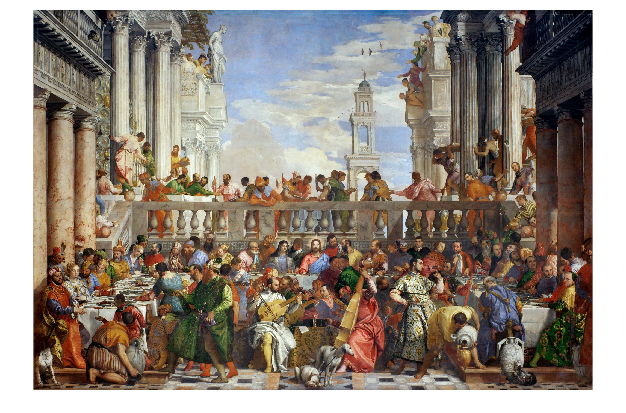

reproduced = imresize(reproduced, [height width], 'bicubic');

imshow(original)

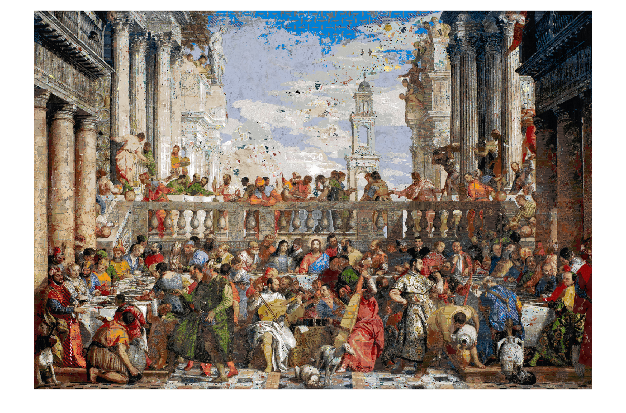

imshow(reproduced)

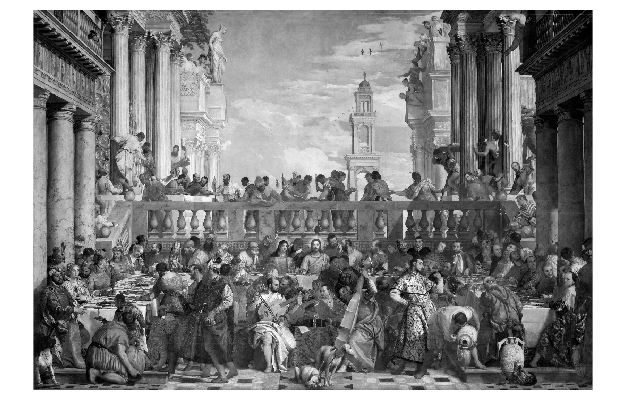

% SNR
o = rgb2gray(original);
r = rgb2gray(reproduced);

imshow(o)

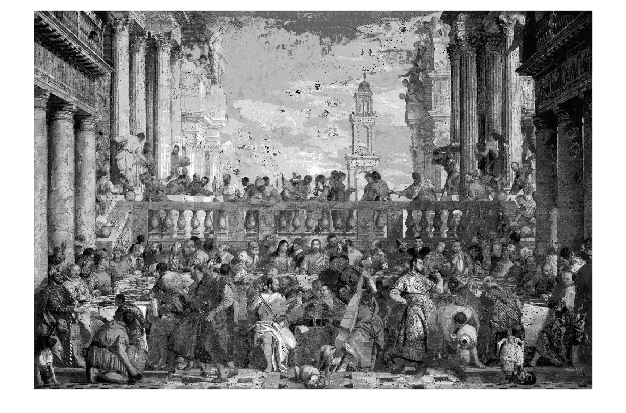

imshow(r)


num = 0;
den = 0;
for i = 1:length(o(:,1,1))
    for j = 1:length(o(1,:,1))
        num = num + o(i,j).^2;
        den = den + (o(i,j) - r(i,j)).^2;
    end
end

SNR = 10*log10(num/den)

SNR = 12.9254

% S-CIELAB
addpath("experimental\scielab\")
PPI = 72;
distances = 0.20:0.20:15;

%cana
D65_wp = [0.9504, 1.0000, 1.0888];
XYZ_reference = rgb2xyz(original, 'WhitePoint', 'd65');
XYZ_reproduced = rgb2xyz(reproduced, 'WhitePoint', 'd65');

scielab_total_data = zeros(3, length(distances));

figure
for j = 1:length(distances)
    D = distances(j) * 39.3700787;
    SPD = PPI * D * tan(pi/180);
    scielab_map = scielab(SPD, XYZ_reference, XYZ_reproduced, D65_wp, 'xyz');
    scielab_total_data(1, j) = mean(scielab_map(:));
    disp((100*1*j) / (3*length(distances)))
end

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    0.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    0.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    1.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    1.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    2.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    2.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    3.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    3.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


     4



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    4.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    4.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    5.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    5.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    6.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    6.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    7.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    7.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


     8



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    8.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    8.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    9.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    9.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   10.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   10.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   11.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   11.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    12



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   12.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   12.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   13.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   13.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   14.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   14.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   15.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   15.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    16



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   16.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   16.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   17.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   17.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   18.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   18.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   19.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   19.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    20



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   20.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   20.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   21.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   21.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   22.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   22.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   23.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   23.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    24



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   24.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   24.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   25.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   25.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   26.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   26.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   27.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   27.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    28



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   28.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   28.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   29.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   29.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   30.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   30.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   31.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   31.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    32



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   32.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   32.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   33.3333



plot(distances, scielab_total_data(1, :), '.-', 'LineWidth', 1, 'MarkerSize', 10);hold on;
drawnow

%pearl
original = im2double(imread("test_images\Pearl_Earing.jpg"));
reproduced = im2double(imread("results\Pearl4.png"));

height = length(original(:,1,1))

height = 800

width = length(original(1,:,1))

width = 559

reproduced = imresize(reproduced, [height width], 'bicubic');

XYZ_reference = rgb2xyz(original, 'WhitePoint', 'd65');
XYZ_reproduced = rgb2xyz(reproduced, 'WhitePoint', 'd65');

for j = 1:length(distances)
    D = distances(j) * 39.3700787;
    SPD = PPI * D * tan(pi/180);
    scielab_map = scielab(SPD, XYZ_reference, XYZ_reproduced, D65_wp, 'xyz');
    scielab_total_data(2, j) = mean(scielab_map(:));
    disp((100*2*j) / (3*length(distances)))
end

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    0.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    1.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    2.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    3.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    4.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    5.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    6.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    7.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


     8



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    8.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    9.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   10.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   11.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   12.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   13.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   14.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   15.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    16



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   16.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   17.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   18.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   19.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   20.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   21.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   22.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   23.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    24



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   24.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   25.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   26.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   27.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   28.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   29.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   30.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   31.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    32



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   32.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   33.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   34.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   35.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   36.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   37.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   38.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   39.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    40



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   40.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   41.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   42.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   43.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   44.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   45.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   46.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   47.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    48



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   48.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   49.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   50.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   51.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   52.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   53.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   54.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   55.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    56



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   56.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   57.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   58.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   59.5556



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   60.4444



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   61.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   62.2222



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   63.1111



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    64



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   64.8889



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   65.7778



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   66.6667



plot(distances, scielab_total_data(2, :), '.-', 'LineWidth', 1, 'MarkerSize', 10);hold on;
drawnow

%pearl
original = im2double(imread("test_images\Starry_Night.jpg"));
reproduced = im2double(imread("results\Starry_Night_full_size.png"));

height = length(original(:,1,1))

height = 950

width = length(original(1,:,1))

width = 1200

reproduced = imresize(reproduced, [height width], 'bicubic');

XYZ_reference = rgb2xyz(original, 'WhitePoint', 'd65');
XYZ_reproduced = rgb2xyz(reproduced, 'WhitePoint', 'd65');

for j = 1:length(distances)
    D = distances(j) * 39.3700787;
    SPD = PPI * D * tan(pi/180);
    scielab_map = scielab(SPD, XYZ_reference, XYZ_reproduced, D65_wp, 'xyz');
    scielab_total_data(3, j) = mean(scielab_map(:));
    disp((100*3*j) / (3*length(distances)))
end

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    1.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    2.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


     4



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    5.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    6.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


     8



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    9.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   10.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    12



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   13.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   14.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    16



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   17.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   18.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    20



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   21.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   22.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    24



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   25.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   26.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    28



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   29.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   30.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    32



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   33.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   34.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    36



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   37.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   38.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    40



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   41.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   42.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    44



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   45.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   46.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    48



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   49.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   50.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    52



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   53.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   54.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    56



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   57.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   58.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    60



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   61.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   62.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    64



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   65.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   66.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    68



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   69.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   70.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    72



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   73.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   74.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    76



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   77.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   78.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    80



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   81.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   82.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    84



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   85.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   86.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    88



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   89.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   90.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    92



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   93.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   94.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


    96



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   97.3333



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   98.6667



Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


   100



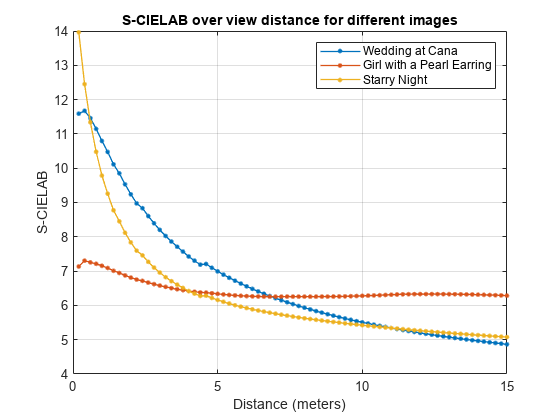

plot(distances, scielab_total_data(3, :), '.-', 'LineWidth', 1, 'MarkerSize', 10);hold on;
drawnow

grid on;
hold off;

title('S-CIELAB over view distance for different images')
xlabel('Distance (meters)')
ylabel('S-CIELAB')
legend('Wedding at Cana','Girl with a Pearl Earring', 'Starry Night')